% Create individual element
freq = 900e6;
vp = physconst('lightspeed');
lambda = vp/freq;
N = 3;   
R = lambda / 4;    % 0.0833 = lambda / 4, 0.1143 space in the bodytube
d = dipole;
d.Length = 0.157;
d.Width = 0.002;

% Orient the antenna element horizontal, parallel, on same axis
d.TiltAxis = 'Y';
d.Tilt = 90;

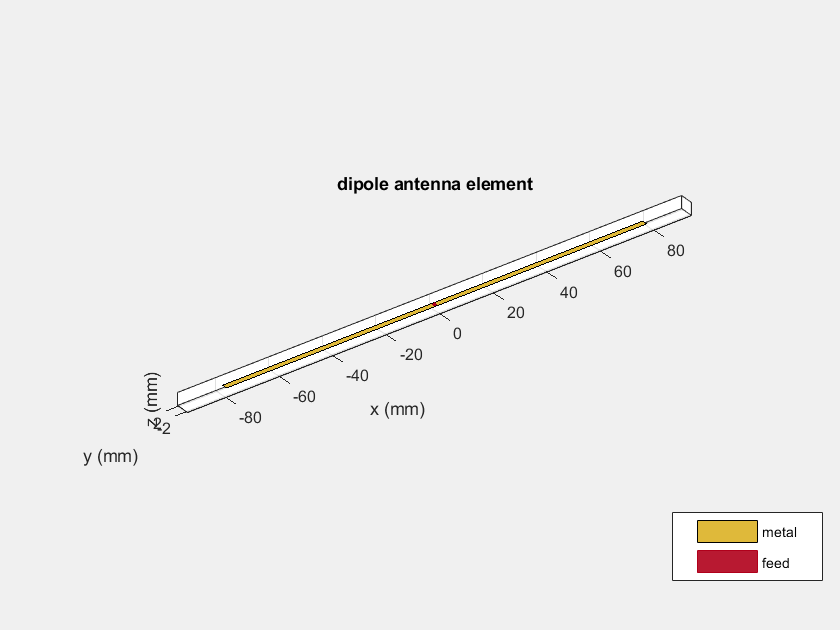

show(d);

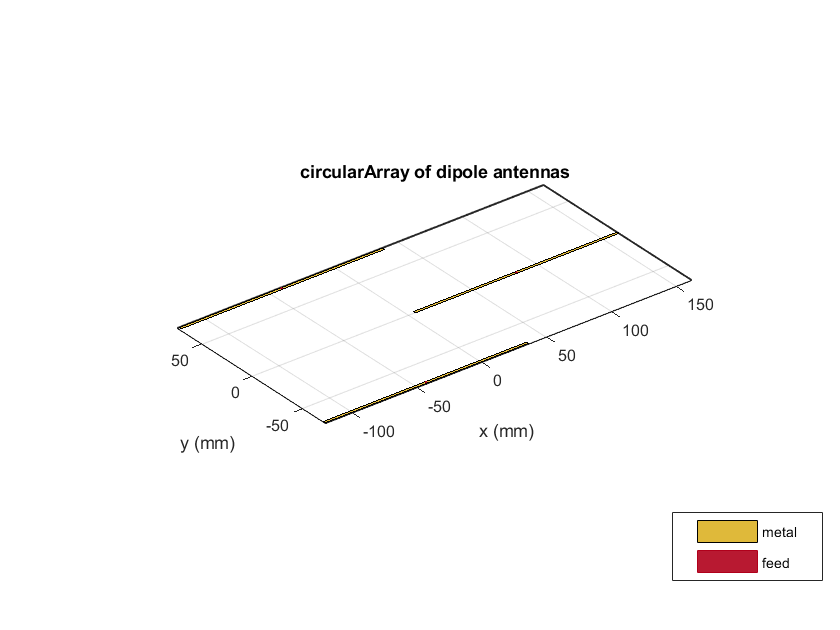

% Create array
dipole_array = circularArray;
dipole_array.Element = d;
dipole_array.Radius = R;
dipole_array.NumElements = N;
h(1) = figure;
show(dipole_array);
axis tight

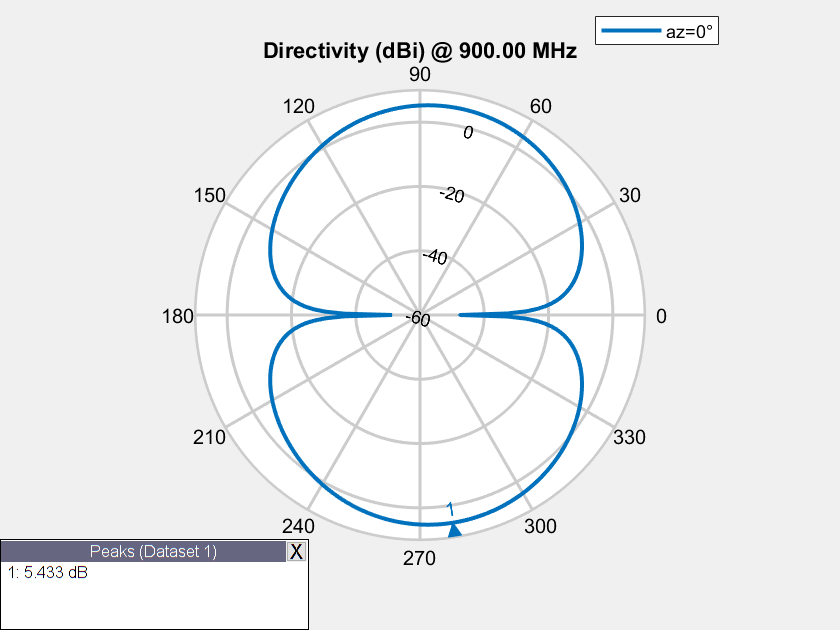

% Polar radiation pattern plot
h(2) = figure;
patternElevation(dipole_array,900e6);

% Using the 'phased' library to create circular array
% uca = phased.UCA(N,R,'Element',d);
% viewArray(uca,'ShowNormals',true,'Title','Uniform Circular Array (UCA)')
% hplot = viewArray(uca)
% view(0,90)

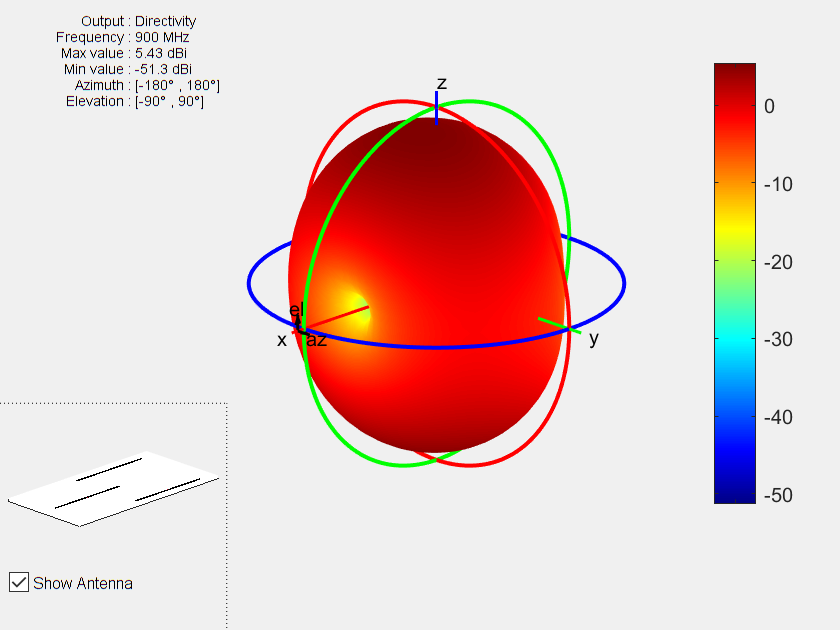

h(3) = figure;
pattern(dipole_array,freq);

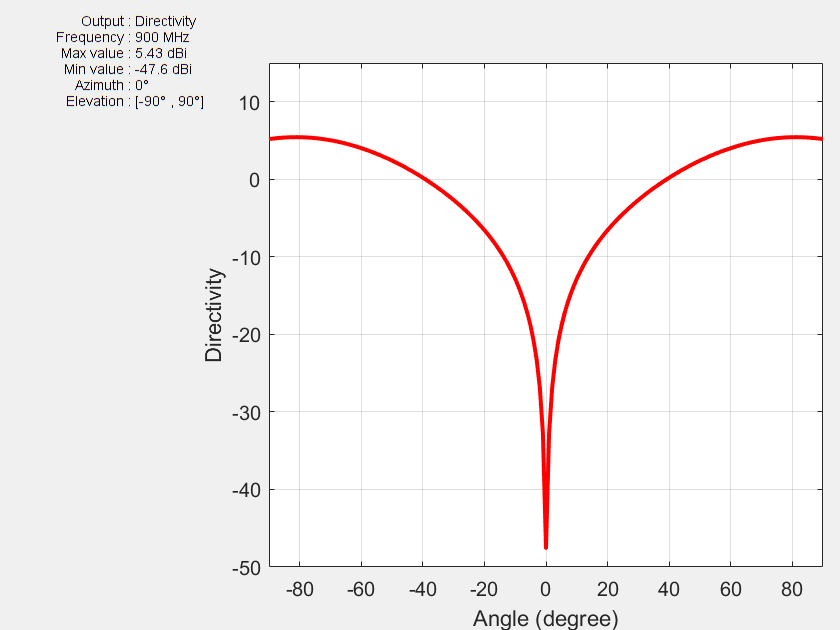

h(4) = figure;
az_angle = 1:180;
el_angle = -90:90;
% azimuth is the angle varying on the horizontal (xy) plane
% elevation is the angle varying up/down the z-axis
pattern(dipole_array, freq, 0, el_angle,'CoordinateSystem','rectangular');
% axis limits of the plot
axis([-90 90 -50 15]);